# Problemas de valor inicial

## Sistema de dos ecuaciones lineales de primer orden


$$y_1^{\prime } =-0\ldotp 5y_1$$
                        
$$y_1 \left(0\right)=4$$



$$y_2^{\prime } =4-0\ldotp 3y_2 -0\ldotp 1y_1$$
       
$$y_2 \left(0\right)=6$$


Grafica la solución entre t=0 y t=2.

% y = [y1;y2]
% y' = [y1;y2]' = f(t, [y1;y2])
% y(0) = [y1(0); y2(0)]

f = @(t,y) [-0.5*y(1);
            4 - 0.3*y(2) - 0.1*y(1)];
t0 = 0;
y0 = [4;6];
tf = 2;
h = 0.5;
[t,y] = TerPar_RK4(f, t0,y0,h,tf);%TerPar_RK4(f,t0,y0,h,tf)

plot(t,y)
xlabel('t')
legend('y1','y2', 'location', 'best')
grid on

## Sistema de dos ecuaciones lineales **homogeneas** de primer orden

### Matriz M de coeficientes (constantes)

#### Sistema 1

% y' = 3*y-2*z     y(0)=1
% z' = 2*y-2*z     z(0)=-1
% yz = [y;z]
% (yz)' = f(y,z)

M = [3,-2;2,-2];
t0 = 0;
yz0 = [1; -1];
tf = 2;
h = 0.1;
f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf);

plot(t,yz)
xlabel('t')
legend('y','z')
grid on

Solución simbólica

syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes)
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)
% yz(t) = [2;1]*exp(2*t) + [-1;-2]*exp(-t)

Valores y vectores propios de M

[V,~] = eig(M)   
% real distinct eigenvalues: D(1,1)=2 and D(2,2)=-1  
% eigenvectors: V(:,1)=[0.8944;0.4472] and V(:,2)=[0.4472;0.8944]
% Solución general
% yzG = K1*V(:,1)*exp(D(1,1)*t)) + K2*V(:,2)*exp(D(2,2)*t))
% Solución particular : condición inicial en t=0
% yz(0) = K1*V(:,1) + K2*V(:,2) = V*[K1;K2] -> [K1;K2]= V\yz(0)
K = V\yz0
K(1)*V(:,1)
K(2)*V(:,2)

#### Sistema 2

% y' =  y+z     y(0)=0.1
% z' = -y+z     z(0)=0.2
% tf = 10

M = [1,1;-1,1];
t0 = 0;
yz0 = [.1; .2];
tf = 5;
h = 0.1;
f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

plot(t,yz)
xlabel('t')
legend('y','z')
grid on
hold on

syms y(t) z(t) yz(t);
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes)
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

[V,~] = eig(M) 
K = V\yz0
K(1)*V(:,1)
K(2)*V(:,2)
fplot(ySolP(t), [t0 tf])
hold off

#### Sistema 3

% y' = -y-6*z    y(0)=0
% z' = 3*y+5*z    z(0)=2
% tf = 10

M = [-1,-6;3,5];
t0 = 0;
yz0 = [0; 2];
tf = 10;
h = 0.1;
f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)
plot(t,yz)
xlabel('t')
grid on
legend('y','z')
hold off

syms y(t) z(t) yz(t);
yz(t) = [y;z];
odes = diff(yz) == M*yz;
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)
fplot (ySolP,[t0 tf])


hold on
grid on

fplot(zSolP,[t0 tf])
legend('ySolP', 'zSolP')
hold off

#### Sistema 4

% y' = -2*y + 5*exp(-t)
% z' = -(y*z^2)/2;
% yz(0) = [2; 4];
% tf = 0.4

t0 = 0;
tf = 0.4;
yz0 = [2; 4];
h = 0.01;
f = @(t,yz) [-2*yz(1)+5*exp(-t);
              -(yz(1)*yz(2)^2)/2];

[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)
plot(t,yz)
xlabel('t')
grid on

syms y(t) z(t) yz(t);
yz(t) = [y;z];
odes = diff(yz) == [-2*y+5*exp(-t); -(y*z^2)/2];
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds);

hold on
fplot (ySolP,[t0 tf])
fplot(zSolP,[t0 tf])
legend('y','z', 'ySolP', 'zSolP')
hold off
%Tal vez aquí sucede algo raro por no ser LINEAL, tendré que preguntar

#### Sistema 5

Pb 25.26 Chapra

Suponga que un proyectil se lanza hacia arriba desde la superficie de la Tierra. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza de la gravedad, hacia abajo. En estas condiciones, se usa un balance de fuerza para obtener,


$$v^{\prime } =-g\frac{R^2 }{{\left(R+y\right)}^2 }$$


donde v = velocidad hacia arriba (m/s), t = tiempo (s), y = altitud (m) medida hacia arriba a partir de la superficie terrestre, g =aceleración gravitacional a la superficie terrestre (≈9.81 m/$s^2$), y R = radio de la tierra (≈6.37 × ${10}^6$ m). Determine la altura máxima que se obtendría si v(t = 0) = 1 400 m/s.

% y' = v
g = 9.81;
R = 6.37e6;

t0 = 0;
tf = 300;
yv0 = [0; 1400];
h = 1;
f = @(t,yv) [yv(2);
             -g*R^2/(R+yv(1))^2];

[t,yv] = TerPar_RK4(f, t0,yv0,h,tf)
plot(t,yv)
xlabel('t')
legend('y','v')
grid on

AltMax = max(yv(1,:))

syms y(t) v(t) yv(t);
yv(t) = [y;v];
odes = diff(yv) == [v; -g*R^2/((R+y)^2)]
conds = yv(0) == yv0
%No hay solución simbólica por ser no-lineal
%[ySolP(t), vSolP(t)] = dsolve(odes,conds);



## Ecuación diferencial lineal homogenea de segundo orden

Con coeficientes constantes


$$y^{\textrm{''}} +ay^{\prime } +\textrm{by}=0$$


Se convierte a un sistema de dos ecuaciones diferenciales de primer orden definiendo una nueva variable $z=y^{\prime }$


$$\begin{array}{l}
y^{\prime } =z\\
z^{\prime } =y^{\textrm{''}} =-a\;z-b\;y
\end{array}$$



$${\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack }^{\prime } =\left\lbrack \begin{array}{cc}
0 & 1\\
-b & -a
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$$


#### Segundo orden 1

$y^{\prime \prime } +y^{\prime } -2y=0$         $y\left(0\right)=3$, $y^{\prime } \left(0\right)=0$

% y'' = -y'+ 2*y
% y' = z
% z' = y'' = -z + 2*y
% yz = [y;z]
M = [0,1;2,-1];
yz0 = [3; 0];
t0 = 0;
tf = 1;
h = 0.05;

f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


yz =     3.0000    3.0074    3.0291    3.0645    3.1131    3.1746    3.2485    3.3347    3.4330    3.5432    3.6653    3.7994    3.9454    4.1036    4.2741    4.4571    4.6530    4.8620    5.0845    5.3210    5.5719
         0    0.2929    0.5729    0.8420    1.1022    1.3550    1.6021    1.8450    2.0850    2.3235    2.5617    2.8008    3.0418    3.2860    3.5343    3.7877    4.0473    4.3139    4.5886    4.8723    5.1659


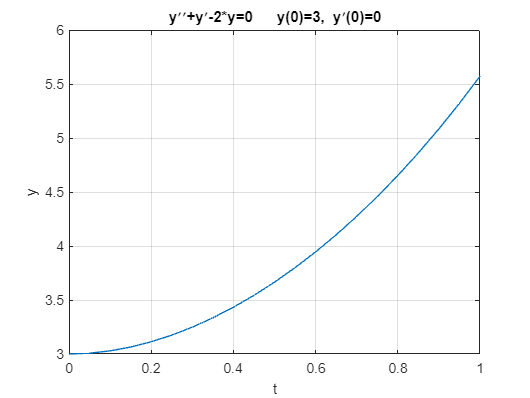

plot(t,yz(1,:));
title('y\prime\prime+y\prime-2*y=0   y(0)=3, y\prime(0)=0');
xlabel('t');
ylabel('y');
grid on;

Solución simbólica de la ecuación de segundo orden

syms y(t)
ode = diff(y,t,2)+diff(y,t,1)-2*y == 0;
yG = dsolve(ode)

$$yG = C_{2}\,{\mathrm{e}}^{t}+C_{1}\,{\mathrm{e}}^{-2\,t}$$

yz0 = [3; 0];
cond1 = y(0) == yz0(1); 
Dy = diff(y);
cond2 = Dy(0) == yz0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

$$yP = {\mathrm{e}}^{-2\,t}+2\,{\mathrm{e}}^{t}$$

Solución simbólica del sistema de 2 ecuaciones de primer orden

syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes)

$$ySolG(t) = C_{1}\,{\mathrm{e}}^{t}-\frac{C_{2}\,{\mathrm{e}}^{-2\,t}}{2}$$

$$zSolG(t) = C_{1}\,{\mathrm{e}}^{t}+C_{2}\,{\mathrm{e}}^{-2\,t}$$

conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = {\mathrm{e}}^{-2\,t}+2\,{\mathrm{e}}^{t}$$

$$zSolP(t) = 2\,{\mathrm{e}}^{t}-2\,{\mathrm{e}}^{-2\,t}$$

Ecuacion diferencial homogenea de segundo orden con coeficientes constantes

Una solución es de la forma $y=e^{\lambda t}$ y el polinomo característico de esta ecuación diferencial lineal de segundo orden de coeficiente constantes es


$$\lambda^2 +\lambda -2=0$$


p = [1,1,-2];
roots(p)

ans =     -2
     1


La solución general es


$$y=C_1 e^{-2t} +C_2 e^t$$


Sistema de 2 ecuaciones de primer orden

[V,D] = eig(M) 

V =     0.7071   -0.4472
    0.7071    0.8944


D =      1     0
     0    -2


K = V\yz0;
K(1)*V(:,1)

ans =      2
     2


K(2)*V(:,2)

ans =      1
    -2


% Valores propios y ecuación característica
% det(M - lamda*I) = 0
% det [0-lamdba,1;-b,-a-lambda] = 0
% -lambda*(-a-lambda) + b = lambda^2 + a*lambda + b = 0
% lambda^2 + lambda -2 
% p = [1,1,-2]

#### Segundo orden 2

$y^{\prime \prime } -y^{\prime } -2y=0$         $y\left(0\right)=0\ldotp 1$, $y^{\prime } \left(0\right)=0\ldotp 2$

M = [0,1;2,1];
yz0 = [.1; .2];
t0 = 0;
tf = 1;
h = 0.05;

f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


yz =     0.1000    0.1105    0.1221    0.1350    0.1492    0.1649    0.1822    0.2014    0.2226    0.2460    0.2718    0.3004    0.3320    0.3669    0.4055    0.4482    0.4953    0.5474    0.6050    0.6686    0.7389
    0.2000    0.2210    0.2443    0.2700    0.2984    0.3297    0.3644    0.4028    0.4451    0.4919    0.5437    0.6008    0.6640    0.7339    0.8110    0.8963    0.9906    1.0948    1.2099    1.3372    1.4778


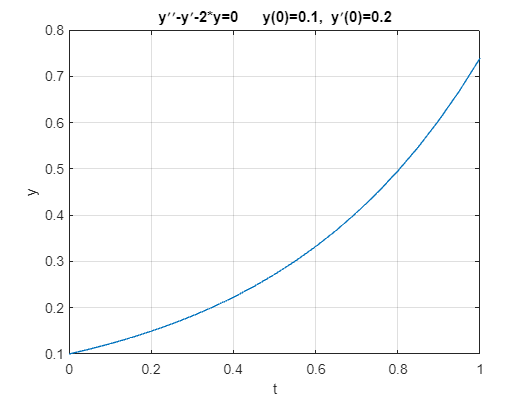

plot(t,yz(1,:));
title('y\prime\prime-y\prime-2*y=0   y(0)=0.1, y\prime(0)=0.2');
xlabel('t');
ylabel('y');
grid on;


syms y(t)
ode = diff(y,t,2)-diff(y,t,1)-2*y == 0;
yG = dsolve(ode)

$$yG = C_{1}\,{\mathrm{e}}^{-t}+C_{2}\,{\mathrm{e}}^{2\,t}$$

yz0 = [.1; .2];
cond1 = y(0) == yz0(1); 
Dy = diff(y);
cond2 = Dy(0) == yz0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

$$yP = \frac{{\mathrm{e}}^{2\,t}}{10}$$


syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes)

$$ySolG(t) = \frac{C_{2}\,{\mathrm{e}}^{2\,t}}{2}-C_{1}\,{\mathrm{e}}^{-t}$$

$$zSolG(t) = C_{1}\,{\mathrm{e}}^{-t}+C_{2}\,{\mathrm{e}}^{2\,t}$$

conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = \frac{{\mathrm{e}}^{2\,t}}{10}$$

$$zSolP(t) = \frac{{\mathrm{e}}^{2\,t}}{5}$$


p = [1,-1,-2];
roots(p)

ans =      2
    -1



[V,D] = eig(M) 

V =    -0.7071   -0.4472
    0.7071   -0.8944


D =     -1     0
     0     2


K = V\yz0;
K(1)*V(:,1)

ans =      0
     0


K(2)*V(:,2)

ans =     0.1000
    0.2000


#### Segundo orden 3

$y^{\prime \prime } +y^{\prime } -6y=0$         $y\left(0\right)=5$, $y^{\prime } \left(0\right)=0$

%z = y'
%z' = y'' = 6y - y'
M = [0,1;6,-1];
yz0 = [5; 0];
t0 = 0;
tf = 10;
h = 0.1;

f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yz = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   

plot(t,yz);
xlabel('t');
ylabel('y');
grid on;

%Resolver la de segundo orden
syms y(t)
ode = diff(y,t,2)+diff(y,t,1)-6*y == 0;
yG = dsolve(ode);
cond1 = y(0) == yz0(1); 
Dy = diff(y);
cond2 = Dy(0) == yz0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

$$yP = 3\,{\mathrm{e}}^{2\,t}+2\,{\mathrm{e}}^{-3\,t}$$


%Resolver todo el sistema
syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes);
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = 3\,{\mathrm{e}}^{2\,t}+2\,{\mathrm{e}}^{-3\,t}$$

$$zSolP(t) = 6\,{\mathrm{e}}^{2\,t}-6\,{\mathrm{e}}^{-3\,t}$$

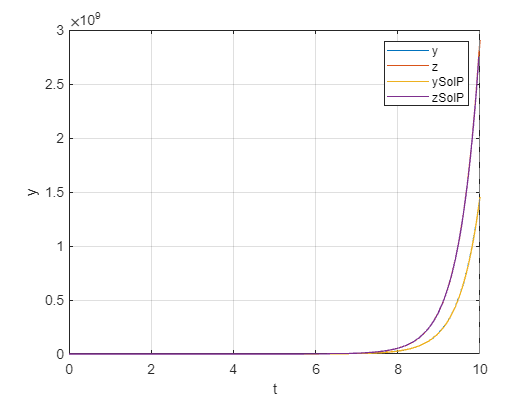


%Graficamos para comparar
hold on
fplot (ySolP,[t0 tf])
fplot(zSolP,[t0 tf])
legend('y','z', 'ySolP', 'zSolP')
hold off

#### Segundo orden 4

Harmonic oscillator

$y^{\prime \prime } +y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

% tf = 10;
%z = y'
M = [0,1;-1,0];
yz0 = [4; 0];
t0 = 0;
tf = 10;
h = 0.1;

f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yz =     4.0000    3.9800    3.9203    3.8213    3.6842    3.5103    3.3013    3.0594    2.7868    2.4864    2.1612    1.8144    1.4494    1.0700    0.6799    0.2830   -0.1168   -0.5154   -0.9088   -1.2932   -1.6646   -2.0194   -2.3540   -2.6651   -2.9496   -3.2046   -3.4275   -3.6163   -3.7689   -3.8838   -3.9600   -3.9965   -3.9932   -3.9499   -3.8672   -3.7458   -3.5870   -3.3924   -3.1639   -2.9037   -2.6146   -2.2993   -1.9611   -1.6032   -1.2293   -0.8432   -0.4486   -0.0496    0.3500    0.7460
         0   -0.3993   -0.7947   -1.1821   -1.5577   -1.9177   -2.2586   -2.5769   -2.8694   -3.1333   -3.3659   -3.5648   -3.7282   -3.8542   -3.9418   -3.9900   -3.9983   -3.9667   -3.8954   -3.7852   -3.6372   -3.4528   -3.2340   -2.9828   -2.7019   -2.3939   -2.0620   -1.7095   -1.3400   -0.9570   -0.5645   -0.1663    0.2335    0.6310    1.0222    1.4031    1.7701    2.1193    2.4474    2.7511    3.0272    3.2731    3.4863    3.6647    3.8064    3.9101    3.9748    3.9997    3.9847    

plot(t,yz);
xlabel('t');
ylabel('y');
grid on;

%Resolver la de segundo orden
syms y(t)
ode = diff(y,t,2)+y == 0;
yG = dsolve(ode);
cond1 = y(0) == yz0(1); 
Dy = diff(y);
cond2 = Dy(0) == yz0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

$$yP = 4\,\cos\left(t\right)$$


%Resolver todo el sistema
syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes);
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = 4\,\cos\left(t\right)$$

$$zSolP(t) = -4\,\sin\left(t\right)$$

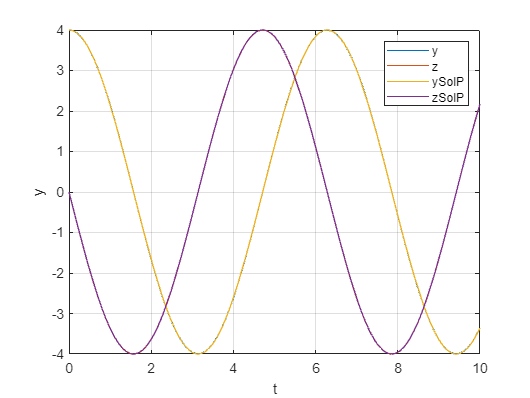


%Graficamos para comparar
hold on
fplot (ySolP,[t0 tf])
fplot(zSolP,[t0 tf])
legend('y','z', 'ySolP', 'zSolP')
hold off

#### Segundo orden 5

Motion of a mass connected to a spring, with viscous friction on the surface and an applied external force.

${3y}^{\prime \prime } +{18y}^{\prime } +102y=10$         $y\left(0\right)=0$, $y^{\prime } \left(0\right)=0$

% tf = 5
%f = @(t,yz) M*yz + b;  b=[0;10/3]
%z = y'

M = [0,1;-102/3,-18/3];
b=[0;10/3];
yz0 = [0; 0];
t0 = 0;
tf = 10;
h = 0.1;

f = @(t,yz) M*yz+b;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yz =          0    0.0134    0.0418    0.0714    0.0943    0.1078    0.1128    0.1119    0.1079    0.1033    0.0994    0.0970    0.0959    0.0958    0.0963    0.0970    0.0977    0.0981    0.0983    0.0984    0.0983    0.0982    0.0981    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980
         0    0.2371    0.3084    0.2708    0.1828    0.0890    0.0153   -0.0290   -0.0461   -0.0441   -0.0320   -0.0174   -0.0050    0.0030    0.0067    0.0070    0.0055    0.0033    0.0012   -0.0002   -0.0009   -0.0011   -0.0009   -0.0006   -0.0003   -0.0000    0.0001    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

plot(t,yz);
xlabel('t');
ylabel('y');
grid on;

%Resolver la de segundo orden
syms y(t)
ode = 3*diff(y,t,2)+18*diff(y,t,1)+102*y == 10;
yG = dsolve(ode);
cond1 = y(0) == yz0(1); 
Dy = diff(y);
cond2 = Dy(0) == yz0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

$$yP = \frac{5}{51}-\frac{\sin\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{17}-\frac{5\,\cos\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{51}$$


%Resolver todo el sistema
syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz+b;
[ySolG(t), zSolG(t)] = dsolve(odes);
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = \left(\frac{5\,\cos\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{34}+\frac{3\,\sin\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{34}\right)\,\left(\frac{2\,\cos\left(5\,t\right)\,{\mathrm{e}}^{3\,t}}{3}-\frac{2}{3}\right)-\frac{2\,\sin\left(5\,t\right)\,{\mathrm{e}}^{3\,t}\,\left(\frac{3\,\cos\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{34}-\frac{5\,\sin\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}}{34}\right)}{3}$$

$$zSolP(t) = \frac{2\,\cos\left(5\,t\right)\,\sin\left(5\,t\right)}{3}-\sin\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}\,\left(\frac{2\,\cos\left(5\,t\right)\,{\mathrm{e}}^{3\,t}}{3}-\frac{2}{3}\right)$$

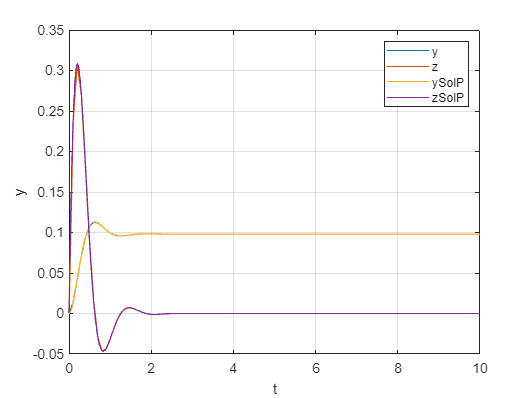

%Aquí es donde comentaba que los dos métodos me arrogaban diferente
%resultados

%Graficamos para comparar
hold on
fplot (ySolP,[t0 tf])
fplot(zSolP,[t0 tf])
legend('y','z', 'ySolP', 'zSolP')
hold off

#### Segundo orden 6

Resuelve el problema siguiente de t=0 a 5.

$y^{\prime \prime } +{0\ldotp 6y}^{\prime } +8y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

%z = y'
M = [0,1;-8,-.6];
yz0 = [4; 0];
t0 = 0;
tf = 5;
h = 0.1;

f = @(t,yz) M*yz;
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yz =     4.0000    3.8442    3.4010    2.7213    1.8714    0.9265   -0.0347   -0.9373   -1.7151   -2.3153   -2.7020   -2.8578   -2.7841   -2.5000   -2.0396   -1.4488   -0.7806   -0.0911    0.5653    1.1399    1.5930    1.8970    2.0369    2.0116    1.8326    1.5228    1.1135    0.6421    0.1487   -0.3274   -0.7506   -1.0912   -1.3279   -1.4483   -1.4501   -1.3399   -1.1328   -0.8504   -0.5188   -0.1666    0.1780    0.4888    0.7439    0.9266    1.0273    1.0429    0.9771    0.8399    0.6458    0.4132
         0   -3.0645   -5.7142   -7.7690   -9.1049   -9.6608   -9.4393   -8.5027   -6.9649   -4.9795   -2.7256   -0.3928    1.8345    3.7906    5.3405    6.3883    6.8823    6.8168    6.2294    5.1958    3.8216    2.2327    0.5642   -1.0508   -2.4906   -3.6546   -4.4689   -4.8911   -4.9115   -4.5520   -3.8623   -2.9149   -1.7979   -0.6072    0.5609    1.6178    2.4884    3.1163    3.4674    3.5306    3.3178    2.8616    2.2112    1.4281    0.5805   -0.2625   -1.0362   -1.6849   -2.1659   -

plot(t,yz);
xlabel('t');
ylabel('y');
grid on;

%Resolver la de segundo orden
syms y(t)
ode = diff(y,t,2)+.6*diff(y,t,1)+8*y == 0;
yG = dsolve(ode);
cond1 = y(0) == yz0(1); 
Dy = diff(y);
cond2 = Dy(0) == yz0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

$$yP = \frac{4\,{\mathrm{e}}^{-\frac{3\,t}{10}}\,\left(791\,\cos\left(\frac{\sqrt{791}\,t}{10}\right)+3\,\sqrt{791}\,\sin\left(\frac{\sqrt{791}\,t}{10}\right)\right)}{791}$$


%Resolver todo el sistema
syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes);
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = \frac{320\,\sqrt{791}\,\left(\frac{3\,{\mathrm{e}}^{-\frac{3\,t}{10}}\,\sin\left(\frac{\sqrt{791}\,t}{10}\right)}{80}+\frac{\sqrt{791}\,{\mathrm{e}}^{-\frac{3\,t}{10}}\,\cos\left(\frac{\sqrt{791}\,t}{10}\right)}{80}\right)}{791}$$

$$zSolP(t) = -\frac{320\,\sqrt{791}\,{\mathrm{e}}^{-\frac{3\,t}{10}}\,\sin\left(\frac{\sqrt{791}\,t}{10}\right)}{791}$$

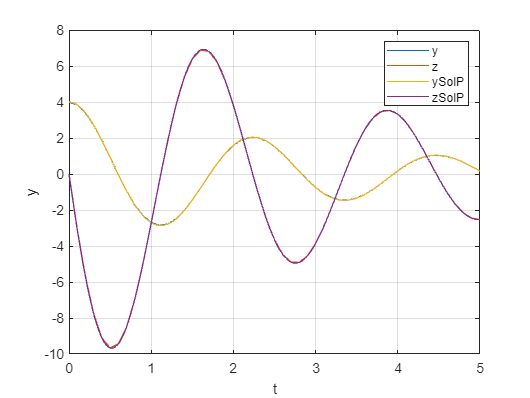

%Aquí también da diferentes expresiones simbólicas, ¿cómo podría compara
%para saber si son iguales?

%Graficamos para comparar
hold on
fplot (ySolP,[t0 tf])
fplot(zSolP,[t0 tf])
legend('y','z', 'ySolP', 'zSolP')
hold off

#### Segundo orden 7

Se trata del oscilador de van der Pol (con amortiguamiento no lineal)


$$\frac{d^2 }{\mathrm{d}t^2 }y-\left(1-y^2 \right)\frac{\mathrm{d}}{\mathrm{d}t}y+y=0$$
          
$$y\left(0\right)=y^{\prime } \left(0\right)=1$$


Grafica la solución entre t=0 y t=10.

%y' = z
%y'' = z' = (1-y^2)*y'- y
yz0 = [1; 1];
t0 = 0;
tf = 10;
h = 0.1;

f = @(t,yz) [yz(2);
             (1-yz(1)^2)*yz(2)-yz(1)];
[t,yz] = TerPar_RK4(f, t0,yz0,h,tf)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yz =     1.0000    1.0945    1.1764    1.2437    1.2954    1.3313    1.3517    1.3575    1.3498    1.3298    1.2985    1.2567    1.2050    1.1437    1.0731    0.9928    0.9025    0.8014    0.6883    0.5621    0.4212    0.2638    0.0883   -0.1063   -0.3198   -0.5499   -0.7906   -1.0322   -1.2619   -1.4662   -1.6348   -1.7627   -1.8507   -1.9034   -1.9274   -1.9288   -1.9130   -1.8840   -1.8450   -1.7978   -1.7440   -1.6843   -1.6191   -1.5488   -1.4732   -1.3920   -1.3047   -1.2107   -1.1092   -0.9990
    1.0000    0.8860    0.7486    0.5961    0.4374    0.2800    0.1294   -0.0110   -0.1401   -0.2583   -0.3670   -0.4684   -0.5650   -0.6592   -0.7540   -0.8519   -0.9559   -1.0689   -1.1937   -1.3330   -1.4889   -1.6620   -1.8493   -2.0425   -2.2244   -2.3666   -2.4310   -2.3796   -2.1912   -1.8780   -1.4855   -1.0739   -0.6937   -0.3726   -0.1170    0.0798    0.2295    0.3441    0.4339    0.5068    0.5689    0.6246    0.6773    0.7296    0.7836    0.8414    0.9049    0.9760    1.0568    

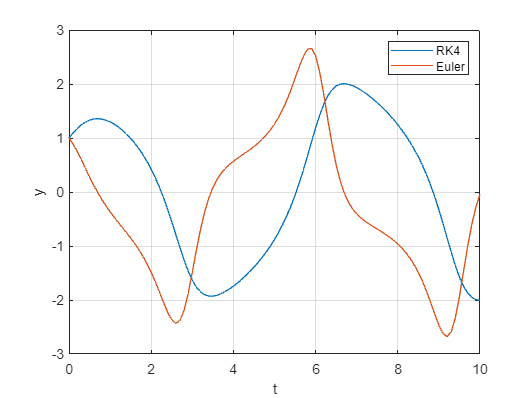

plot(t,yz);
hold on
xlabel('t');
ylabel('y');
grid on;
legend('RK4','Euler')


%Resolver la de segundo orden
% syms y(t)
% ode = diff(y,t,2)-(1-y^2)*diff(y,t,1)+y == 0;
% yG = dsolve(ode);
% cond1 = y(0) == yz0(1); 
% Dy = diff(y);
% cond2 = Dy(0) == yz0(2); 
% conds = [cond1 cond2];
% yP = dsolve(ode, conds)

%No hay solución simbólica debido a que es  no-lineal